clear
clf

data = readmatrix('rpalus_data_02222023.csv')

data = 1.0e+03 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN
         0    0.0001    0.0004    0.0002    0.0003    0.0003         0
    0.3200    0.0002    0.0003    0.0003    0.0003    0.0003    0.3200
    0.7300    0.0002       NaN    0.0002    0.0003    0.0002    1.0500
    0.7250    0.0004    0.0002    0.0002    0.0002    0.0003    1.7750
    0.7180    0.0007    0.0004    0.0002    0.0004    0.0003    2.4930
    0.7180    0.0008    0.0005    0.0003    0.0004    0.0003    3.2110
    0.7190    0.0008    0.0007    0.0003    0.0004    0.0002    3.9300
    0.7220    0.0008    0.0009    0.0003    0.0004    0.0003    4.6520
    0.7080    0.0008    0.0013    0.0003    0.0004    0.0003    5.3600


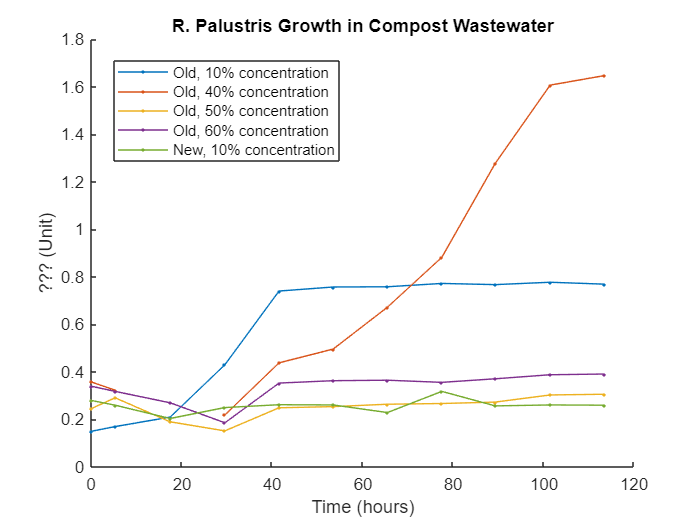


time = data(:, 7) / 60;  % hours
old_10percent = data(:, 2);
old_40percent = data(:, 3);
old_50percent = data(:, 4);
old_60percent = data(:, 5);
new_10percent = data(:, 6);

hold on
plot(time, old_10percent, '.-');
plot(time, old_40percent, '.-');
plot(time, old_50percent, '.-');
plot(time, old_60percent, '.-');
plot(time, new_10percent, '.-');
title("R. Palustris Growth in Compost Wastewater")
xlabel("Time (hours)") %changed from min
ylabel("??? (Unit)") %TODO: What is the unit here? + how to translate to cell count
legend("Old, 10% concentration", "Old, 40% concentration", "Old, 50% concentration", ...
       "Old, 60% concentration", "New, 10% concentration", 'location', 'best')
hold off